Apartado 1

Ka = -1.6000;
Kb = 8;
K3 = 0.7000;
K2 = 8;
K1 = 22;
K0 = 0;
Kw = 3.4000;
Ks = 0.1000;
ts = 1;
T = 0.1;

Apartado 2

s = zpk('s');
G = (Ka*s+Kb)/(K3*s^3+K2*s^2+K1*s+K0)

G =
 
      -2.2857 (s-5)
  ---------------------
  s (s+6.821) (s+4.608)
 
Continuous-time zero/pole/gain model.
Model Properties


Apartado 3

Gz = c2d(G, T, 'zoh')

Gz =
 
  -0.0064445 (z+0.5832) (z-1.651)
  -------------------------------
    (z-1) (z-0.6308) (z-0.5056)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


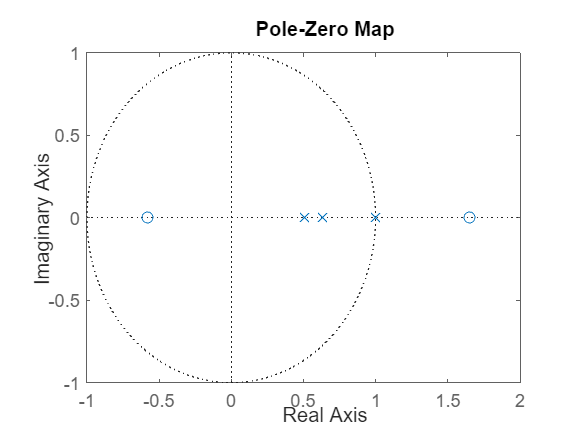

pzmap(Gz)

El sistema es de orden 3 debido a que el grado del denominador máximo es 3

El sistema es de tipo 1 debido a que eso viene definido a la cantidad de polos en z = 1